load('GlobalBest2000.mat')
N1 = 96;
c = physconst('lightspeed');
fmin = 5e9;
fmax = 10e9;
fc = 7e9;
lambda = c/fc;

% Method 1:
% Patch Element Spec
patchElement = patchMicrostrip;
patchElement.Length = 0.49*lambda;
patchElement.Width = 0.8*patchElement.Length;
patchElement.GroundPlaneLength = 0.6*lambda;
patchElement.GroundPlaneWidth = 0.4*lambda;
patchElement.Height = 0.01*lambda;
patchElement.FeedOffset = [patchElement.Length/4 0];
% patchElement.Tilt = 90;
patchElement.TiltAxis = [0 1 0];

% x position
xpos = zeros(1,N1);
xpos(1:2:N1) = patchElement.Length;
xpos(2:2:N1) = -patchElement.Length;

% Best position
best = sort(GlobalBest.Position)
best = best(1:N1);

% Patch Array
confarraydef = conformalArray;
confarraydef.Element = patchElement;
confarraydef.ElementPosition = [xpos' best' zeros(1,N1)']
confarraydef.ArraySize;
show(confarraydef)

% Illustrates 3d response to array
% pattern(confarraydef,fc)

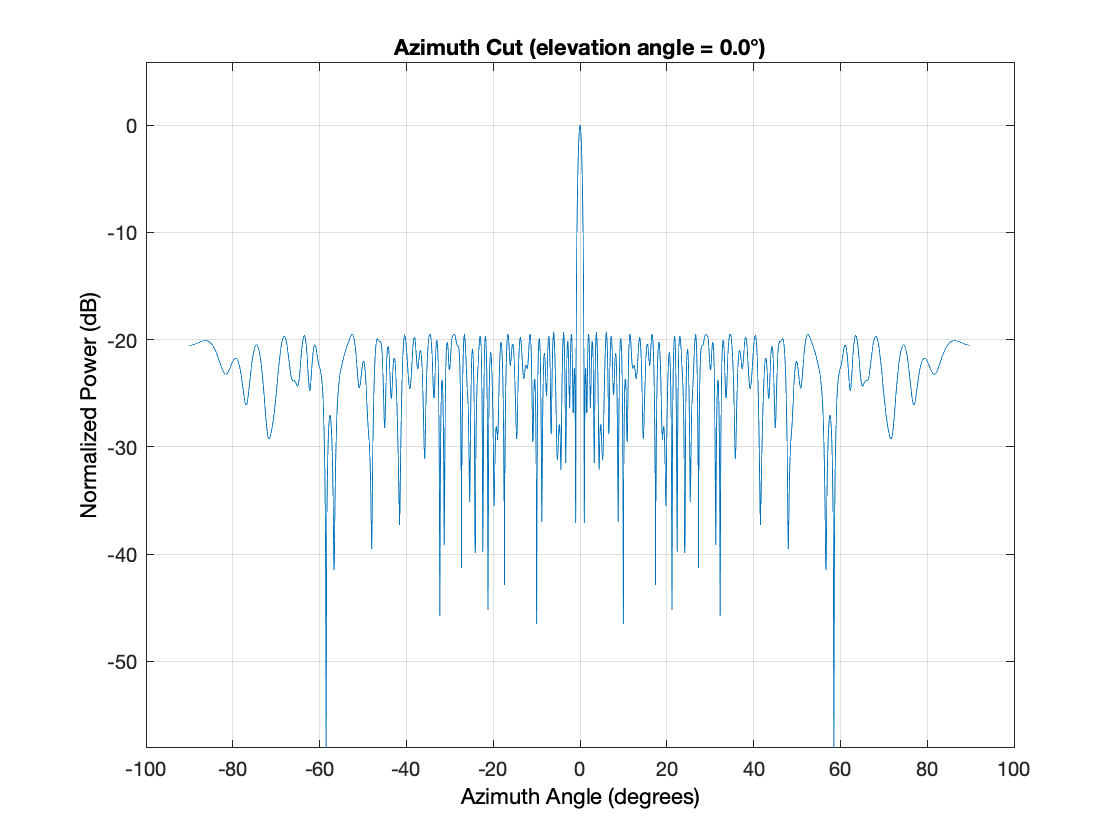

% Method 2:
% Gather AF information (Element(default): isotropic)
theta = [-90:.1:90];
arr = phased.ConformalArray('ElementPosition',[zeros(1,N1);GlobalBest.Position;zeros(1,N1)]);
pattern(arr,fc,theta,0,'PropagationSpeed',c, ...
     'CoordinateSystem','rectangular','Type','powerdb')

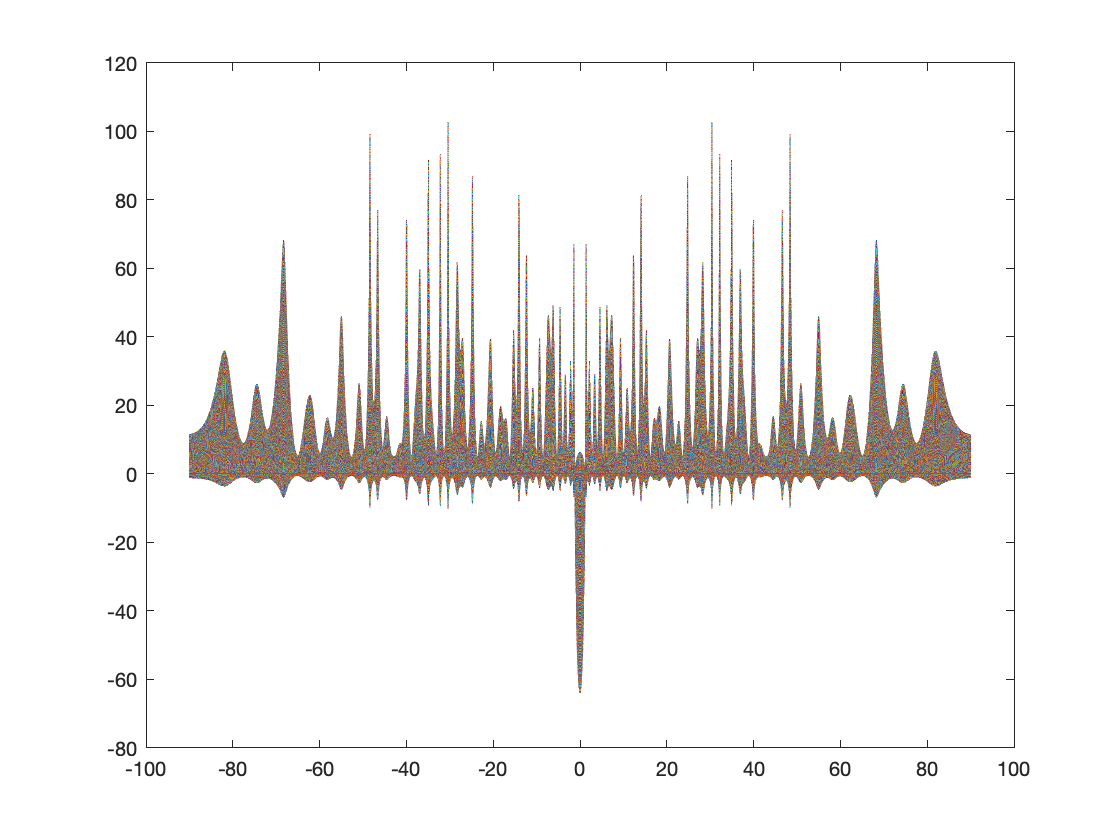


% Gather Element pattern info (Element: Microstrip patch)
% elementPat = pattern(patchElement,fc,[-90:.1:90],0);
% pattern(patchElement,fmin,theta,0)
% pattern(patchElement,fmax,theta,0)

min = pattern(patchElement,fmin,theta,0);
max = pattern(patchElement,fmax,theta,0);
afmin = pattern(arr,fmin,theta,0);
afmax = pattern(arr,fmax,theta,0);

finalMin = afmin * min;
plot(theta,finalMin)

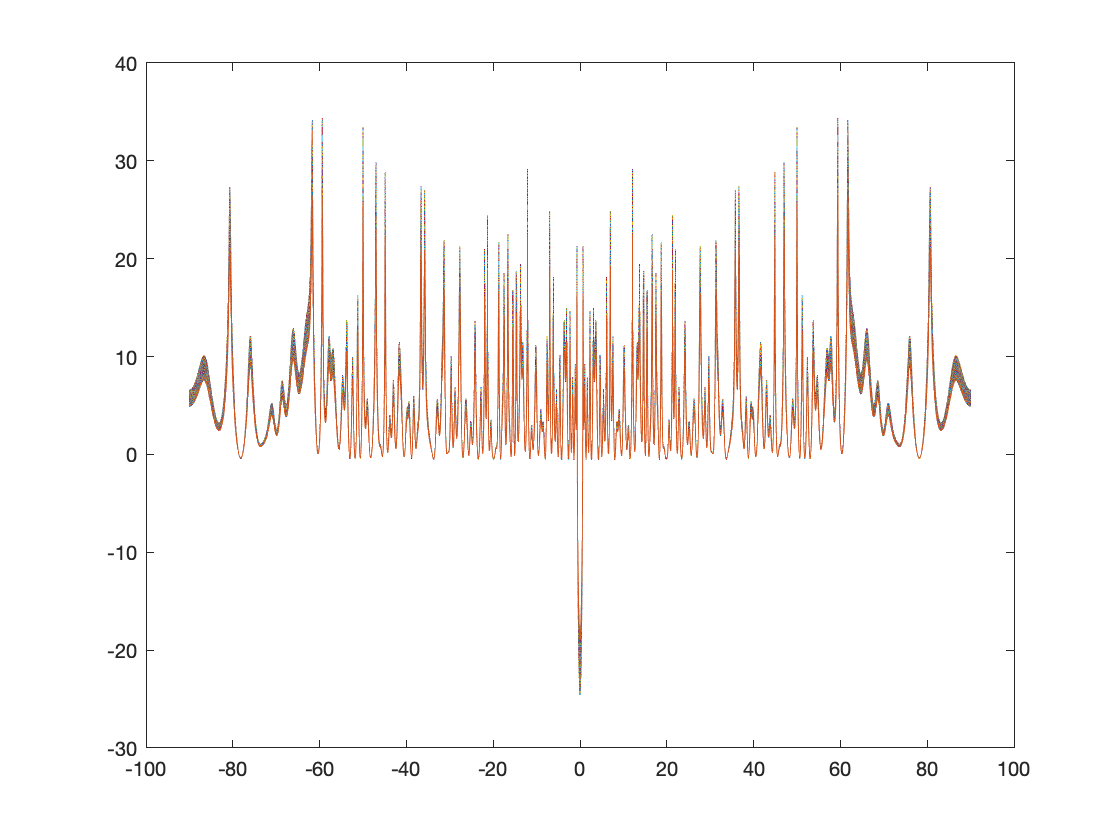

finalMax = afmax * max;
plot(theta,finalMax)